**Test of 'four column' resolution function.**

This is a test script for adapting the current simple polly resolution function into it's 4 column equivalent where the resolution is given.

Start by making a R1 version of the model as usual, convert this as previously and plot everything out to make sure it has all loaded in properly.

[problem,controls] = r1ToProblemDef('r1Model.mat')

problem =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 28
                 params: [1×28 double]
             paramNames: {1×28 cell}
            paramConstr: {1×28 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.7115e-09 3.1708e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[5.0000e-10 7.0000e-06]  [1.0000e-10 5.0000e-06]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [1 0.1432]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 0.2000]}
    scalefactorFitYesNo: [1 1]
              nQzshifts: 1
               qzshifts: 0
           qzshiftNames: {'Qz Shifts 1'}
          qzshiftConstr: {[-0.0300 0

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 'no'



[outProb,results] = RAT(problem,controls)

outProb = struct with fields:
           ssubs: 7.9925e+00
     backgrounds: 2.7115e-09
         qshifts: 0
    scalefactors: 1
          nbairs: 2.0740e-06
          nbsubs: 6.0063e-06
     resolutions: 4.1058e-02
    calculations: [1×1 struct]
     allSubRough: 2.4134e+00


results = struct with fields:
    reflectivity: {[90×2 double]}
      Simulation: {[92×2 double]}
    shifted_data: {[90×3 double]}
       layerSlds: {[10×3 double]}
     sldProfiles: {[525×2 double]}
       allLayers: {[0]}



plotRefSLD(outProb,results)

oldResolution = results.reflectivity{1};

Being a Rascal 1 model, we need to replace the data with the four column version. Load this in....

[header,data] = hdrload('PLP001536.dat')

header = 'Q (1/A)	 Ref	 dRef (SD)	 dq(FWHM, 1/A)'

data =    8.7866e-03   9.4961e-01   2.3361e-02   5.0837e-04
   9.1365e-03   9.9476e-01   2.0819e-02   5.2873e-04
   9.5006e-03   1.0146e+00   1.8726e-02   5.4991e-04
   9.8795e-03   9.6219e-01   1.6288e-02   5.7195e-04
   1.0274e-02   9.7644e-01   1.4857e-02   5.9489e-04
   1.0684e-02   9.6977e-01   1.3253e-02   6.1875e-04
   1.1111e-02   9.5230e-01   1.1804e-02   6.4358e-04
   1.1556e-02   9.7753e-01   1.1367e-02   6.6942e-04
   1.2018e-02   1.0031e+00   1.1070e-02   6.9630e-04
   1.2500e-02   9.7619e-01   9.7881e-03   7.2428e-04


Column 4 here appears to be just dq, whereas we need dq/q, so convert this....

data(:,4) = data(:,4)./data(:,1)

data =    8.7866e-03   9.4961e-01   2.3361e-02   5.7858e-02
   9.1365e-03   9.9476e-01   2.0819e-02   5.7870e-02
   9.5006e-03   1.0146e+00   1.8726e-02   5.7882e-02
   9.8795e-03   9.6219e-01   1.6288e-02   5.7893e-02
   1.0274e-02   9.7644e-01   1.4857e-02   5.7903e-02
   1.0684e-02   9.6977e-01   1.3253e-02   5.7912e-02
   1.1111e-02   9.5230e-01   1.1804e-02   5.7921e-02
   1.1556e-02   9.7753e-01   1.1367e-02   5.7929e-02
   1.2018e-02   1.0031e+00   1.1070e-02   5.7936e-02
   1.2500e-02   9.7619e-01   9.7881e-03   5.7944e-02


We need a simulation at zero resolution (because we're working on a resolution function), and should be able to do this by setting the resolution to zero in RAT

problem.resolutions = eps

problem =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 28
                 params: [1×28 double]
             paramNames: {1×28 cell}
            paramConstr: {1×28 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.7115e-09 3.1708e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[5.0000e-10 7.0000e-06]  [1.0000e-10 5.0000e-06]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [1 0.1432]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 0.2000]}
    scalefactorFitYesNo: [1 1]
              nQzshifts: 1
               qzshifts: 0
           qzshiftNames: {'Qz Shifts 1'}
          qzshiftConstr: {[-0.0300 0


[outProb,results_zero] = RAT(problem,controls)

outProb = struct with fields:
           ssubs: 7.9925e+00
     backgrounds: 2.7115e-09
         qshifts: 0
    scalefactors: 1
          nbairs: 2.0740e-06
          nbsubs: 6.0063e-06
     resolutions: 2.2204e-16
    calculations: [1×1 struct]
     allSubRough: 2.4134e+00


results_zero = struct with fields:
    reflectivity: {[90×2 double]}
      Simulation: {[92×2 double]}
    shifted_data: {[90×3 double]}
       layerSlds: {[10×3 double]}
     sldProfiles: {[525×2 double]}
       allLayers: {[0]}


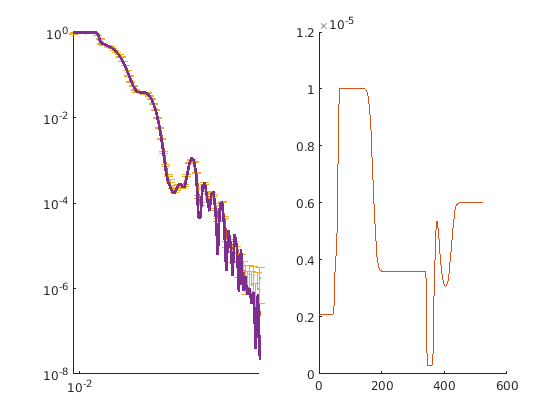


plotRefSLD(outProb,results_zero)

This works. Now have everything needed to work on the resolution function. Made resolution4column which simply steps through the polly resolution function but takes the value of the resolution at each point from resolution array rather than from a constant value. Then..

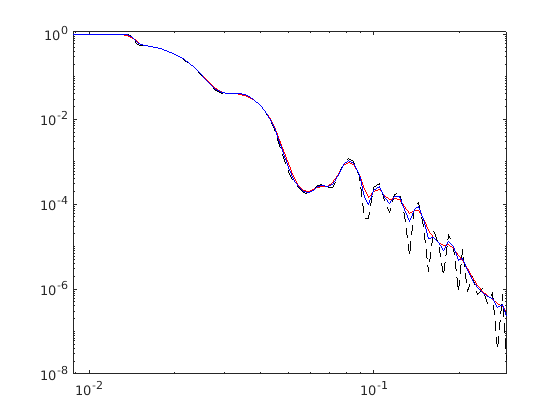

figure;
clf


simulation = results_zero.reflectivity{1};

newResolution = resolution4Column(simulation(:,1),simulation(:,2),data(:,4));

plot(simulation(:,1),simulation(:,2),'k--')

hold on

plot(simulation(:,1),newResolution,'r-')

plot(simulation(:,1),oldResolution(:,2),'b-')
set(gca,'YScale','log','XScale','log')
ylim([1e-8 1.2])